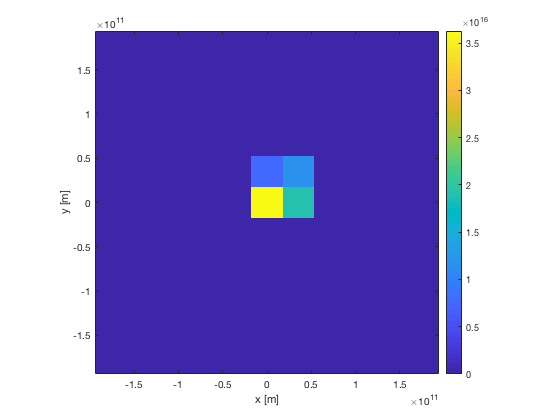

load('DataforTestScript.mat')

particles = Particle(xv0(4:6,1),'Velocity',n_charges,n_masses,xv0(1:3,1), 0, 1, Nt);
%% Inputs: Energy/Velocity, String: 'Energy' or 'Velocity', n_charges, n_masses, initial positions, start time, end time, time steps

VV = Velocity_Verlet([x_grid(1), x_grid(end);y_grid(1),y_grid(end);z_grid(1),z_grid(end)], [Nx, Ny, Nz], 1, particles, hit_objective, E_x, E_y, E_z);
%% Inputs: Dimensions, Resolutions, Array of Particles, Function Handle Objective Function, E_fields (3) or Potential (1)

VV = VV.calculateF_dF;
VV.plotdFdEx